# Diffusion Map on Real Data

- **Roseland**: In order to accelerate the algorithm, this algorithm is based on SVD. The default number landmark is chosen $\sqrt{n}$. Please refer to [Shen and Wu, (2019)](https://arxiv.org/abs/2001.00801) for more detail.

- **Self-tune**: The affinity matrix is created by $k(x_i,x_j)=\exp\left(\frac{\|x_i-x_j\|^2}{\epsilon_i\epsilon_j}\right)$. Please refer to [Zelnik-Manor & Perona, (2005)](https://proceedings.neurips.cc/paper/2004/file/40173ea48d9567f1f393b20c855bb40b-Paper.pdf) for more detail.

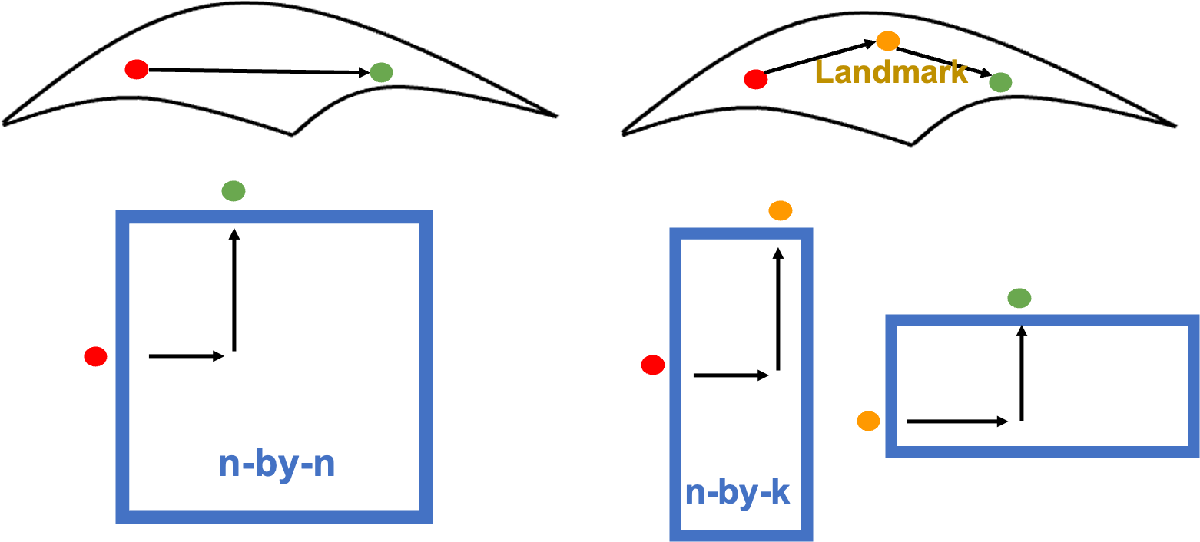

## Fisheriris dataset

- The database contains 150 iris flower infomation. Each data has 4 information, sepal length, sepal width, petal length and petal width.

- There are 3 classes, Setosa, Versicolour and Virginica. Each class contains 50 data.

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
% load fisheriris
load("irismat.mat")
bandwidth = 3.5;
[U, S] = DMapBasic(meas, 100, 4, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 100.
(info) The first 10% number of points in bandwidth neighborhood is 100.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


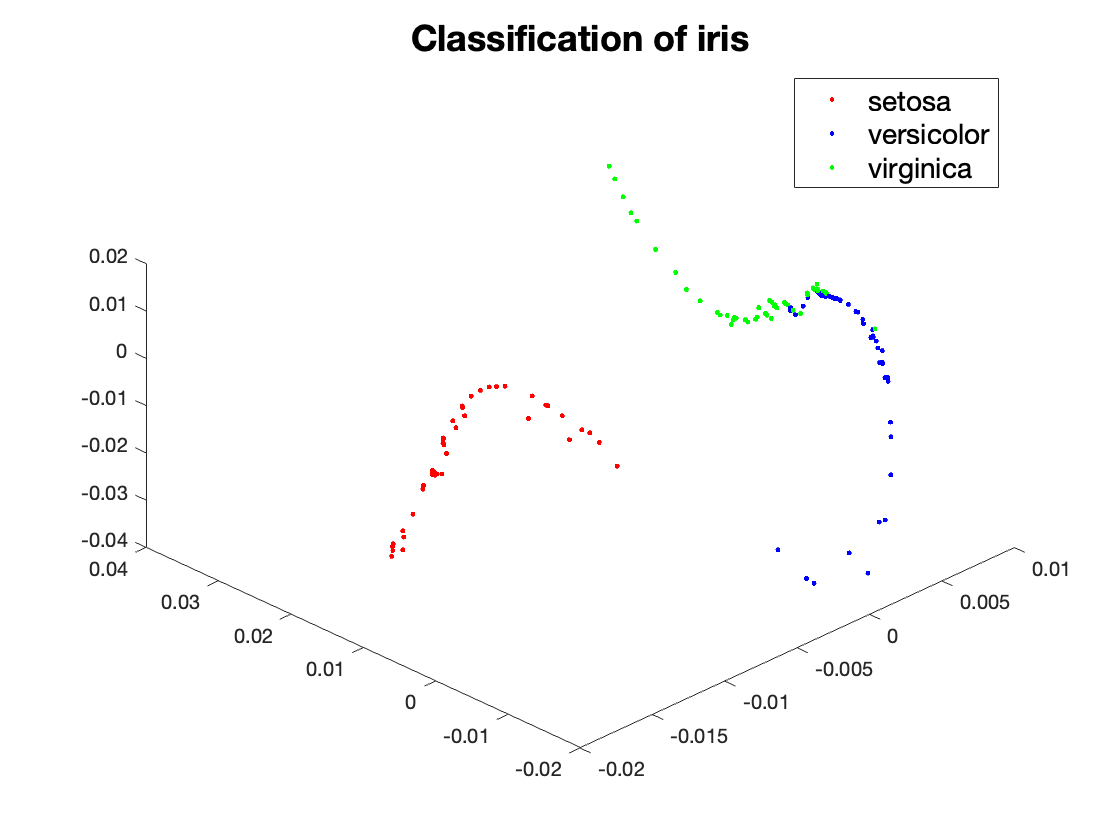

figure
hold on
plot3(U(species==1, 1), U(species==1, 2), U(species==1, 3), 'r.')
plot3(U(species==2, 1), U(species==2, 2), U(species==2, 3), 'b.')
plot3(U(species==3, 1), U(species==3, 2), U(species==3, 3), 'g.')
lgd = legend({'setosa', 'versicolor', 'virginica'}, 'FontSize', 14);
title('Classification of iris', 'Fontsize', 18, 'FontWeight', 'bold')
set(lgd,'Location', 'northeast')
view([-45 45])

## MNIST dataset

- This data set is randomly chosen from this [website](https://github.com/sunsided/mnist-matlab).

- The database contains 5000 digital images with size 28x28.

- There are 10 class. Each class contains 400-600 images.

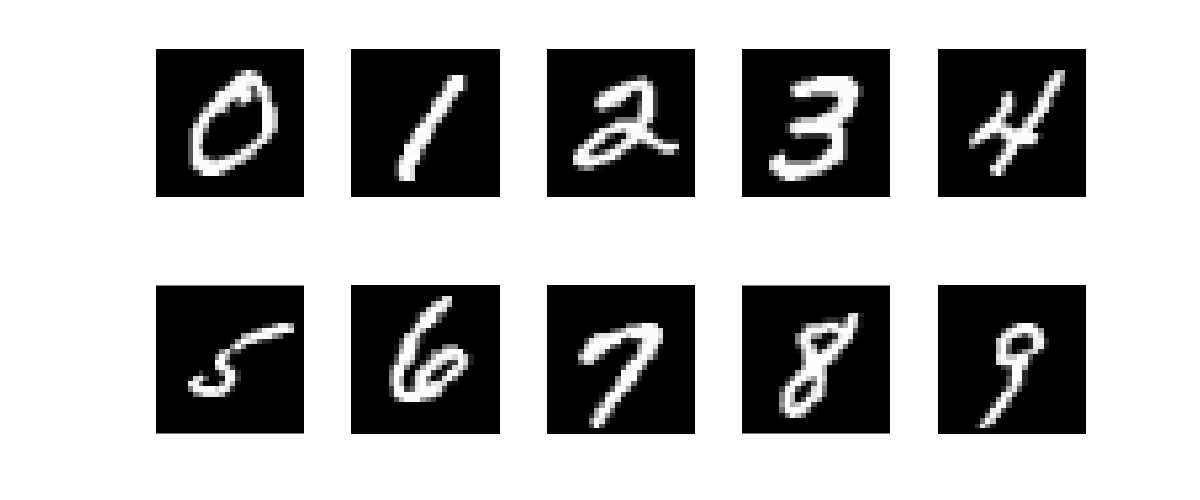

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
% [images, labels, ~] = digitTrain4DArrayData;
load ('mnist.mat')
Roseland_bool = true;
default_land_mark = false;
land_mark = 200;

% flatten
images = reshape(images, [], 5000)';

% dimension reduction via DM
if Roseland_bool
    if default_land_mark
        [U, S] = DMapRoseland(images, 1000, 4);
    else
        [U, S] = DMapRoseland(images, 1000, 4, land_mark);
    end
else
    [U, S] = DMapBasic(images, 1000, 4);
end

Step 1: Use k-means to find landmark.
Step 2: Construct bandwidth of kernel function.
(info) Now, there are 0% distance being truncated.
(info) Now, the median number of reference points colse to one point is 199.
(info) Now, the first 10% number of points in bandwidth neighborhood is 199.
Step 3: Construct affinity matrix
Step 4: Compute the degree matrix. Note that W = Wref*Wref^T.
Step 5: Solve the eigenvectors by SVD.


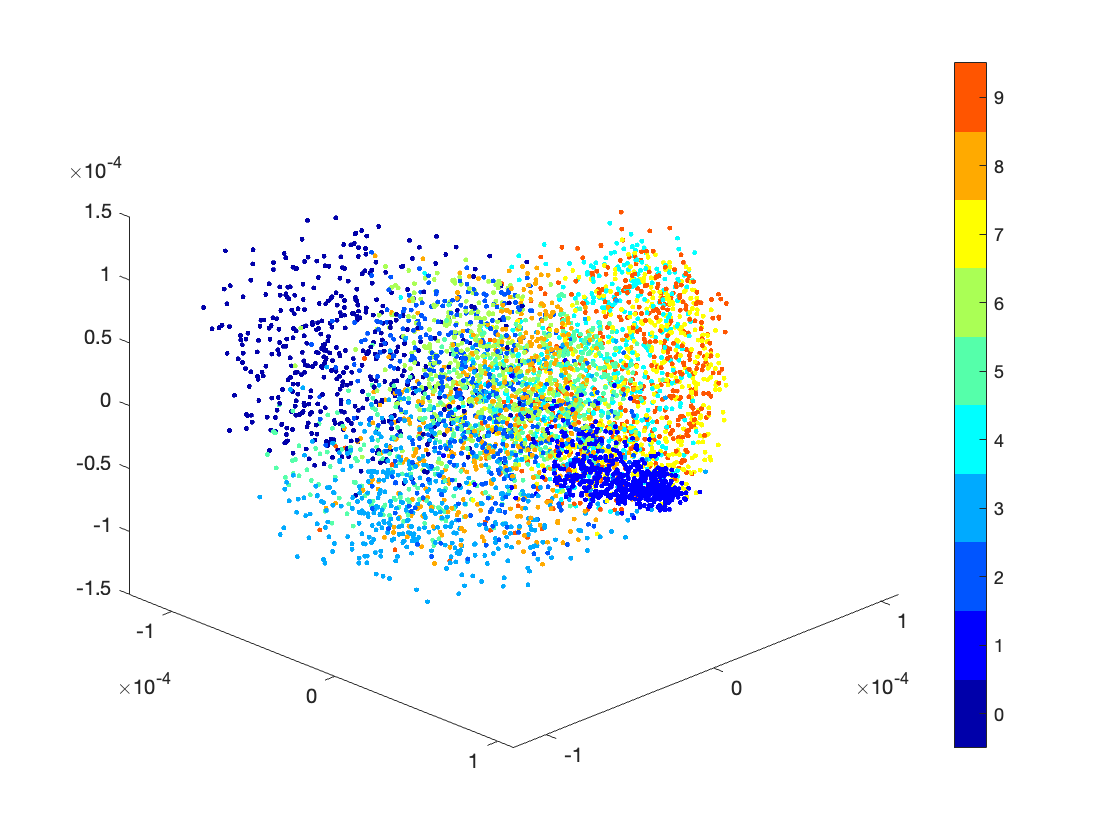


figure
hold on
jetcustom = jet(10);
colormap(jetcustom);
cb = colorbar;
cb.Ticks = (0:0.1:0.9)+0.05;
cb.TickLabels = num2cell(0:1:9) ; 

for i = 1:10
    idx = (labels==i-1);
    plot3(U(idx, 1), U(idx, 2), U(idx, 3), '.', 'Color', jetcustom(i, :));
end
view([45, 30])

## ECG dataset

- This dataset is from website [kaggle](https://www.kaggle.com/shayanfazeli/heartbeat), called the [PTB Diagnostic ECG Database](https://www.physionet.org/content/ptbdb/1.0.0/). 

- The database contains 14552 heartbeat pulses from 290 people.

- There are two categories: normal and abnormal, where there are 10506 abnormal pulses and 4046 normal pulses.

- Moreover, diagnostic class contains: Myocardial infarction, Cardiomyopathy/Heart failure, Dysrhythmia and so on.

The wave shape is as following figure

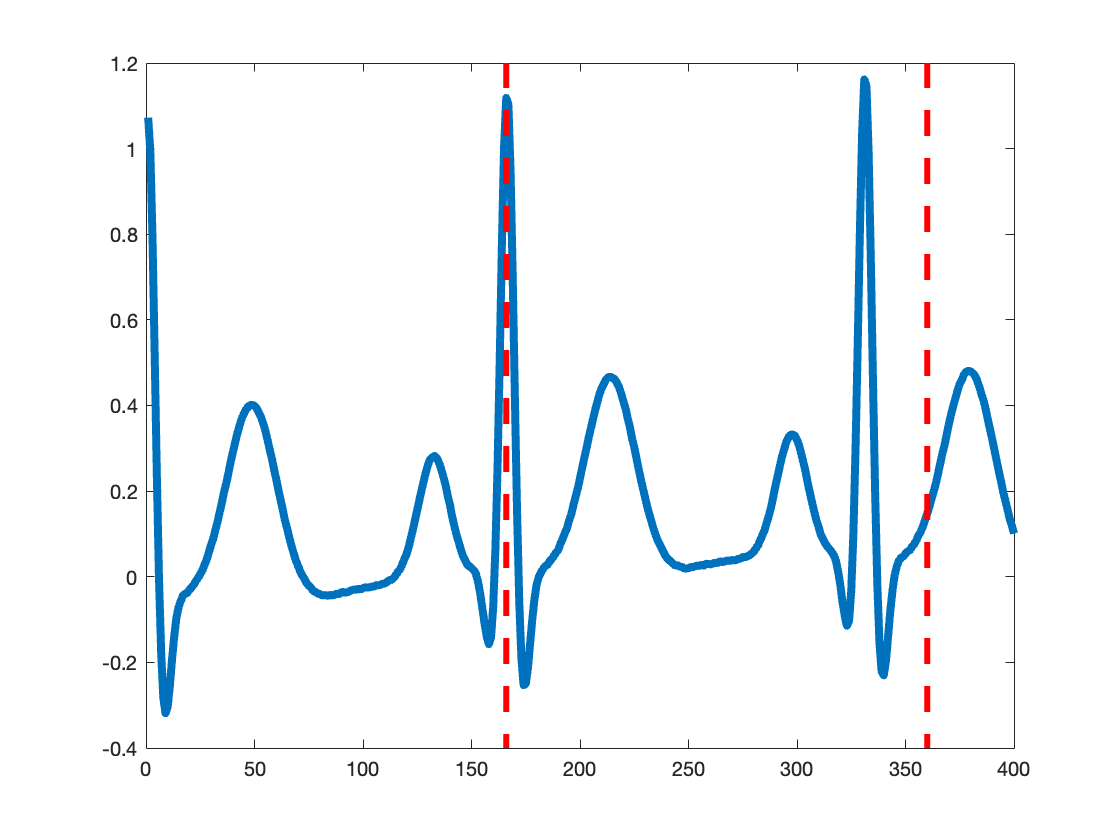

- All the pulses are cropped and padded with zeroes.

- Every pulse is with 187 dimension.

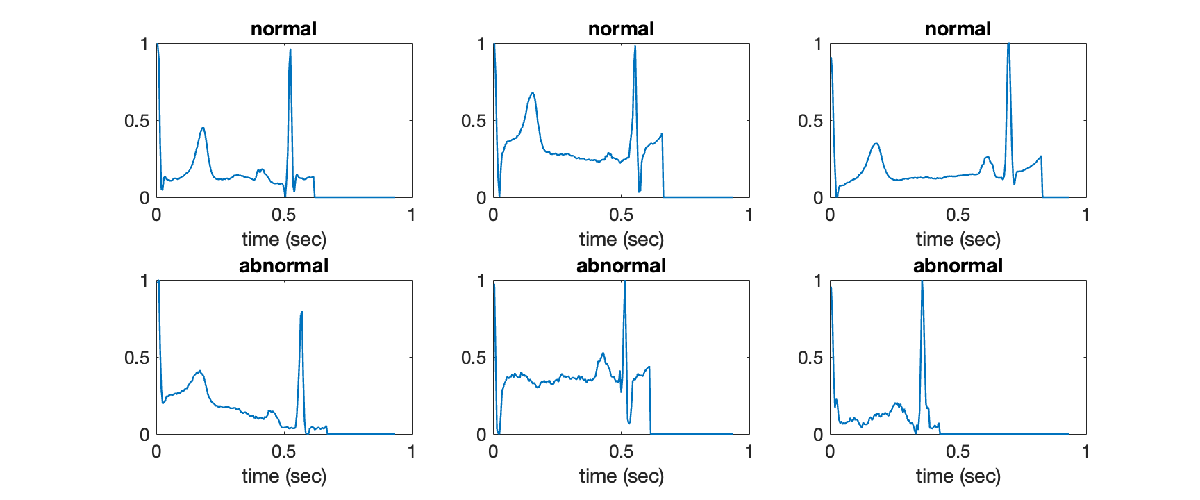

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
load('ECGdataset.mat')
[U, S] = DMapRoseland(X, 300, 20);

Step 1: Use k-means to find landmark.
(info) The number of landmark is chosen: 120.
Step 2: Construct bandwidth of kernel function.
(info) Now, there are 3.9891% distance being truncated.
(info) Now, the median number of reference points colse to one point is 118.
(info) Now, the first 10% number of points in bandwidth neighborhood is 107.
Step 3: Construct affinity matrix
Step 4: Compute the degree matrix. Note that W = Wref*Wref^T.
Step 5: Solve the eigenvectors by SVD.


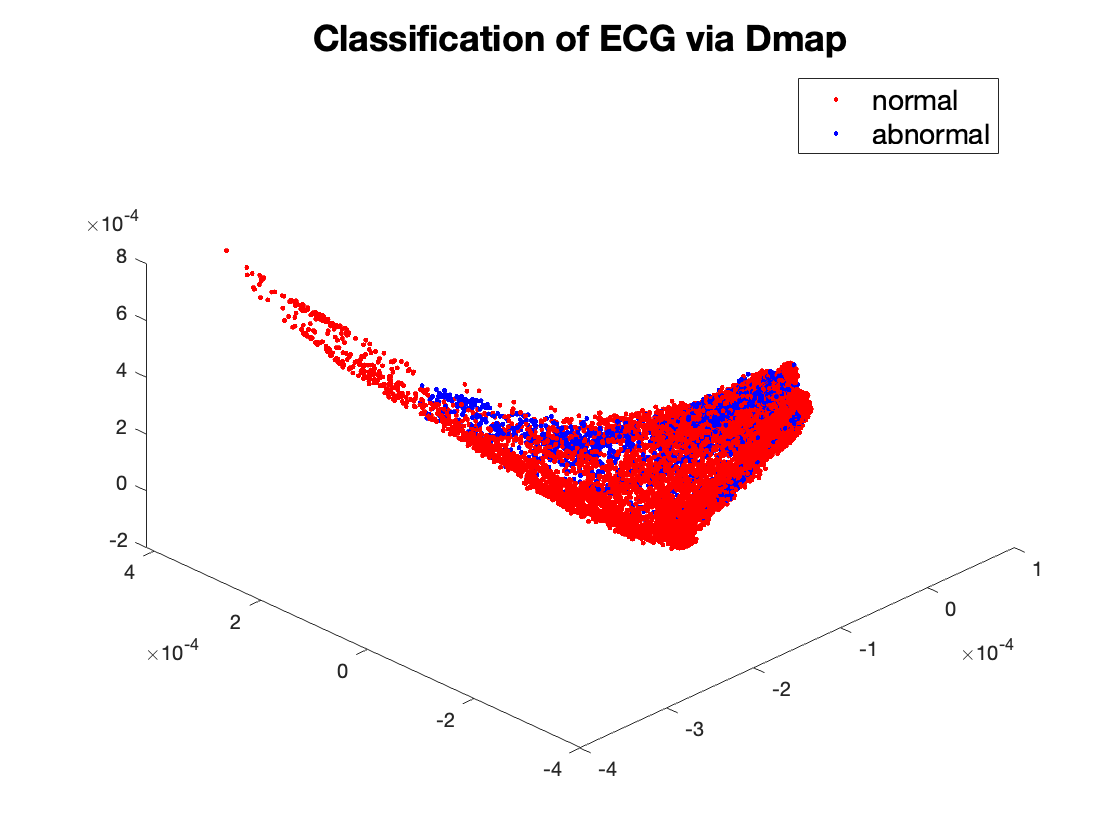

figure
hold on
plot3(U(Y==1, 1), U(Y==1, 2), U(Y==1, 3), 'r.')
plot3(U(Y==0, 1), U(Y==0, 2), U(Y==0, 3), 'b.')
lgd = legend({'normal', 'abnormal'}, 'FontSize', 14);
title('Classification of ECG via Dmap', 'Fontsize', 18, 'FontWeight', 'bold')
set(lgd,'Location', 'northeast')
view([-45 45])

## EEG spectrum

- This dataset is from Physionet, which is called [Sleep-EDF Database](https://physionet.org/content/sleep-edf/1.0.0/). 

- The database contains 4462 EEG  epochs from 5 people.

- EEG is a brain signals and the channel of this EEG is Fpz-Cz, which sampled at 100 Hz. Please refer to this [website](https://kknews.cc/zh-tw/news/jzreylq.html) for more detail.

- The sleep stages are reduced to 5 stages, Awake, REM, N1, N2, N3. Please refer to this [website](https://tamhd.org/sleep-stages/) for more detail.

- Please refer to this [website](https://sleep-laboratory-at-ntu.webnode.tw/%E5%B8%B8%E8%A6%8B%E5%95%8F%E9%A1%8C/%E4%BD%95%E8%AC%82%E7%9D%A1%E7%9C%A0%EF%BC%9F/) or this [website](https://www.joiiup.com/knowledge/content/1466) for more detail of the relationshop between sleep stages and EEG singals.

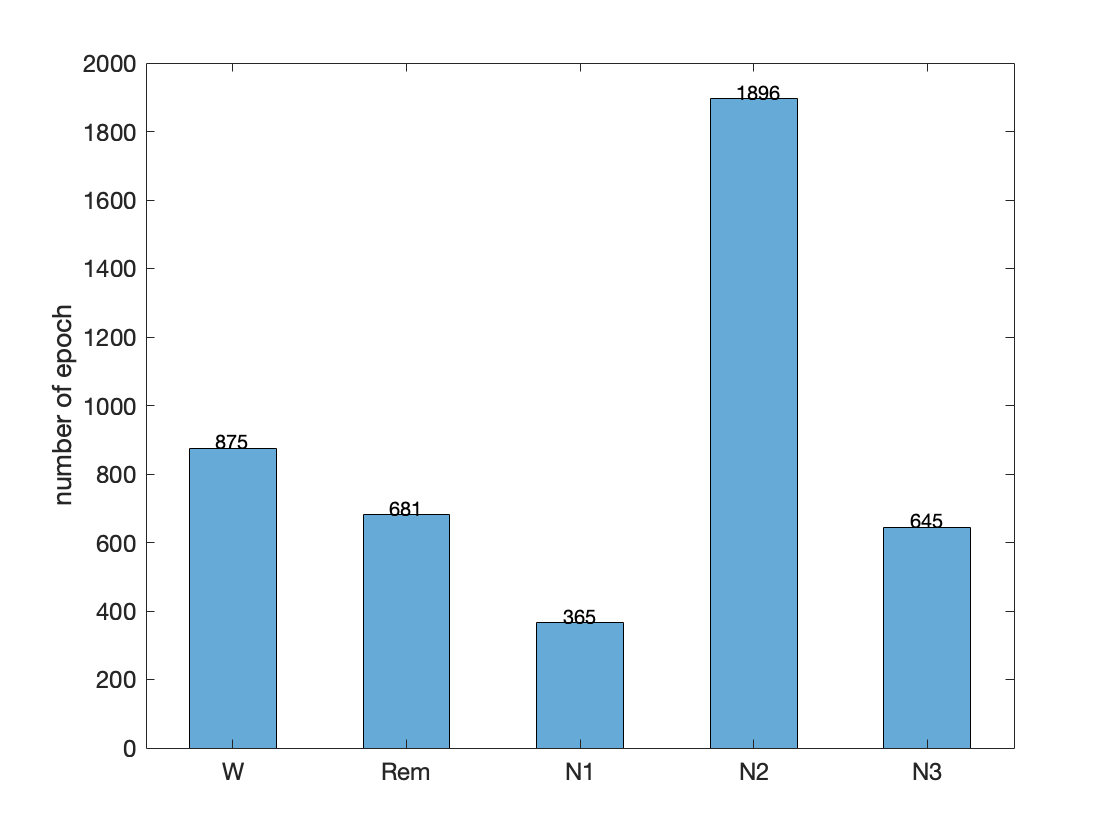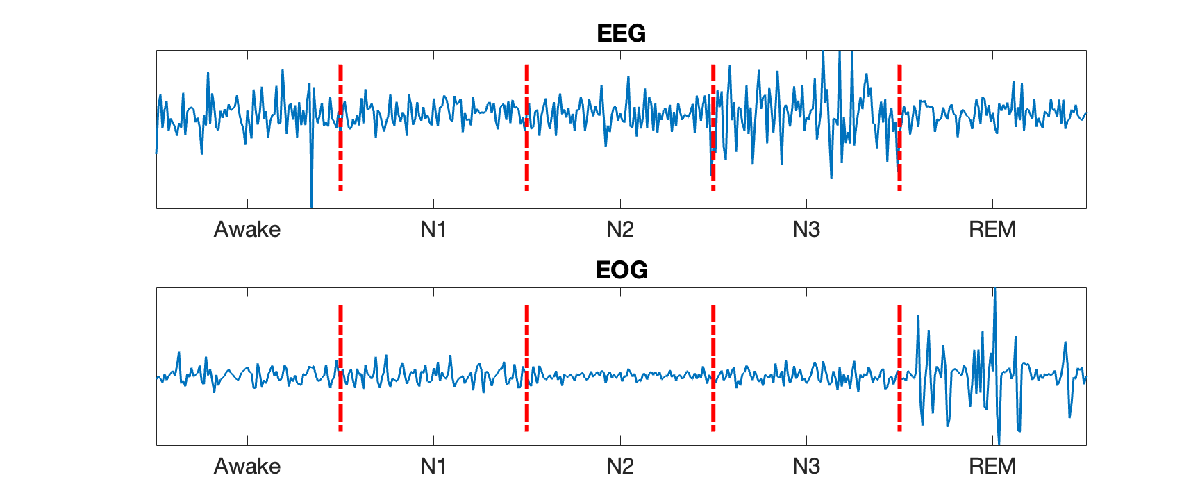

### Preprocessing

- The data are preprocessed by scattering transformation, which is based on wavelet transformation.

- The following is showed wavelet transformation of a epoch.

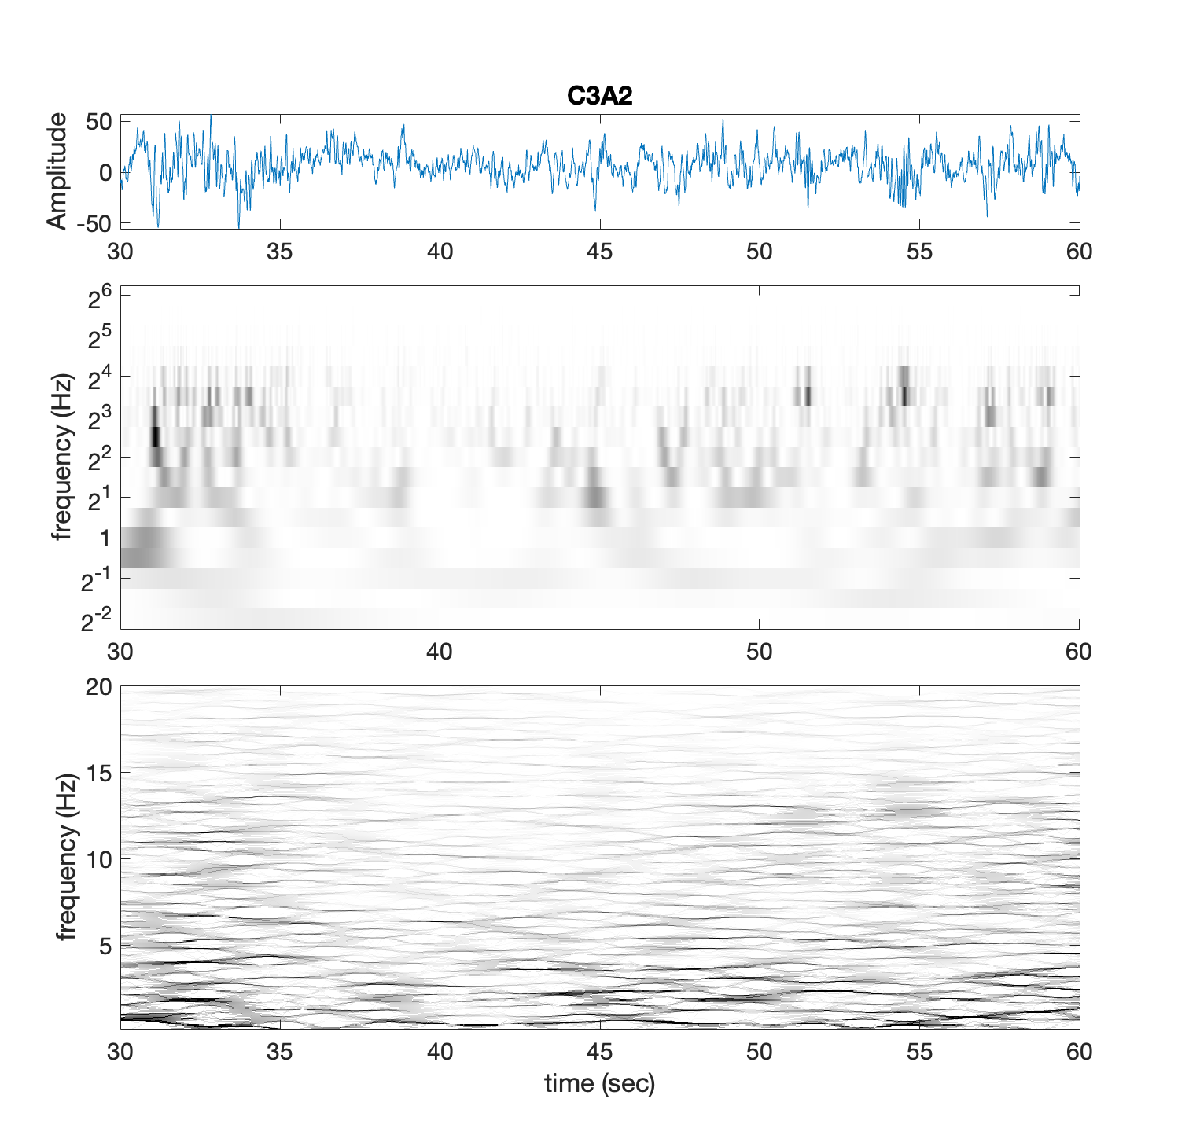

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
load('EEG_spectrum.mat')
% [U, S] = DMapBasic(X, 1000, 3);
% [U, S] = DMapRoseland(X, 300, 20);
[U, S] = DMap4EEG(X, 3);

The kernel bandwidth is 21.6424.


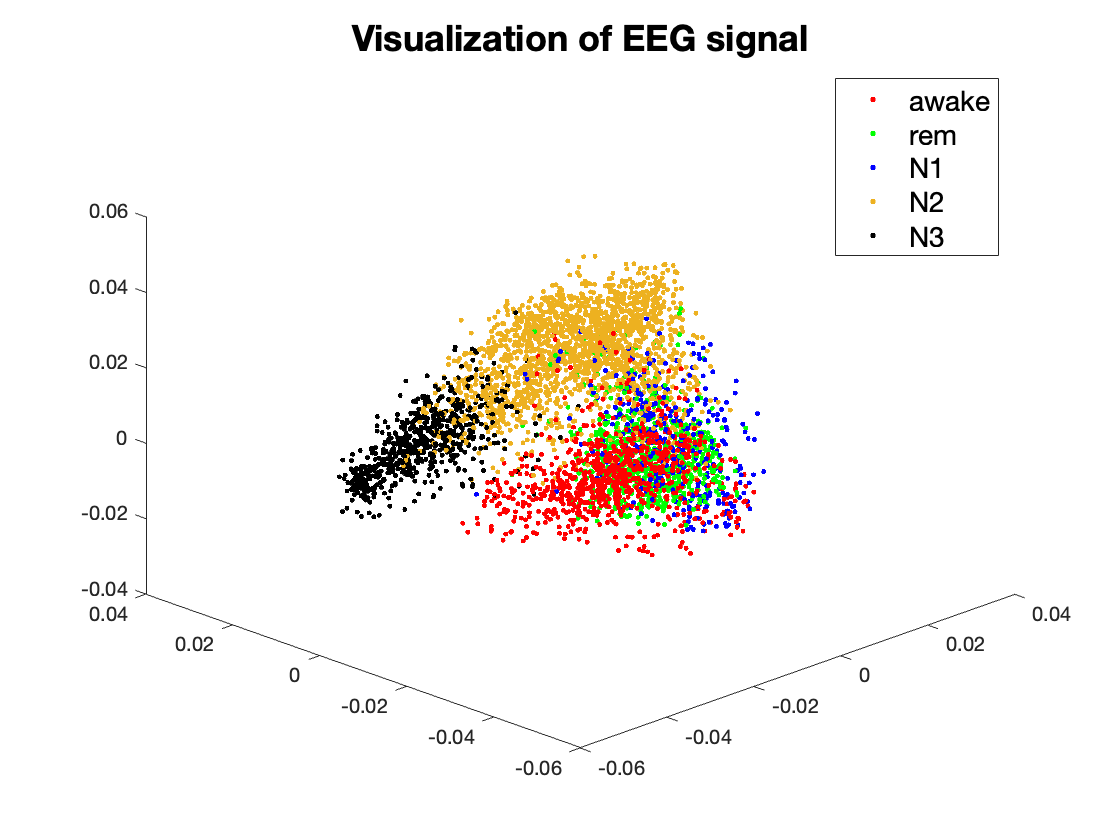


figure
jetcustom = ["r", "g", "b", "#EDB120", "k"];
hold on
for i = 1:5
    idx = (Y==i);
    plot3(U(idx, 1), U(idx, 2), U(idx, 3), '.', 'Color', jetcustom(i), 'MarkerSize', 7)
end
lgd = legend({'awake', 'rem', 'N1', 'N2', 'N3'}, 'FontSize', 14);
set(lgd,'Location', 'northeast')
title('Visualization of EEG signal', 'Fontsize', 18)
view([-45 30])